function [varargout] = MRI_func_GEO(sXYZ,func,varargin)
%UNTITLED2 此处显示有关此函数的摘要
%   此处显示详细说明

if isnumeric(sXYZ)
    sXYZ = MRI_read_Data(sXYZ);
end
switch func
    case 'jacobi2_mat'
        output = XYZ_jacobi_mat(sXYZ,varargin{:});
    case 'jacobi3_det'
        output = XYZ_jacobi3_det(sXYZ,varargin{:});
    case 'jacobi3_mat'
        output = XYZ_jacobi3_mat(sXYZ,varargin{:});
    case 'fit_affine'
        output = XYZ_fit_affine(sXYZ,varargin{:});
    case 'field_linear'
        output = XYZ_field_linear(sXYZ,varargin{:});
    case 'mov2abs'
        output = XYZ_mov2abs(sXYZ,varargin{:});
    case 'resize'
        output = XYZ_resize(sXYZ,varargin{:});
    case 'smooth'
        output = XYZ_smooth(sXYZ,varargin{:});
    case 'sym_dim'
        output = XYZ_sym_dim(sXYZ,varargin{:});
    case 'sym_field'
        output = XYZ_sym_field(sXYZ,varargin{:});
    case 'combine'
        output = XYZ_combine(sXYZ,varargin{:});
end

if ~iscell(output)
    output = {output};
end
varargout = output;
end



$$\textrm{jacobi}=\left\lbrack \begin{array}{cc}
\textrm{dxu} & \textrm{dxv}\\
\textrm{dyu} & \textrm{dyv}
\end{array}\right\rbrack =R\left(\theta \right)R\left(-\varphi \right)\left\lbrack \begin{array}{cc}
\lambda 1 & 0\\
0 & \lambda 2
\end{array}\right\rbrack R\left(\varphi \right),\textrm{面积变化}=\left|\textrm{jacobi}\right|=\textrm{dxudyv}-\textrm{dxvdyu}=\lambda 1\lambda 2,\textrm{尺度变化}=\frac{\lambda 1+\lambda 2}{2}=\frac{\textrm{dxu}+\textrm{dyv}}{2}$$



$$\begin{array}{l}
\left\lbrack \begin{array}{ccc}
\textrm{dxu} & \textrm{dyu} & \textrm{dzu}\\
\textrm{dxv} & \textrm{dyv} & \textrm{dzv}
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
\textrm{dxu} & \textrm{dxv}\\
\textrm{dyu} & \textrm{dyv}\\
\textrm{dzu} & \textrm{dyv}
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
{\textrm{dxu}}^2 +{\textrm{dyu}}^2 +{\textrm{dzu}}^2  & \textrm{dxudxv}+\textrm{dyudyv}+\textrm{dzudzv}\\
\textrm{dxudxv}+\textrm{dyudyv}+\textrm{dzudzv} & {\textrm{dxv}}^2 +{\textrm{dyv}}^2 +{\textrm{dzv}}^2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
E & F\\
F & G
\end{array}\right\rbrack \\
\lambda_{1,2} =0\ldotp 5\left(E+G\pm \sqrt{4F^2 +{\left(E-G\right)}^2 }\right)
\end{array}$$


function [output] = XYZ_jacobi2_mat(XYZ)
% 计算贴图坐标场的jacobi矩阵特征值，评估形变大小

if size(XYZ,3) == 2
    XYZ = cat(3,XYZ,XYZ(:,:,1)*0);
end

fdx_1 = @(x) (x(1:end-1,:)+x(2:end,:))/2; fdx_2 = @(x) (x(:,1:end-1)+x(:,2:end))/2; 
dxu = diff(XYZ(:,:,1),1,2); dxu = fdx_1(dxu); dxv = diff(XYZ(:,:,1),1,1); dxv = fdx_2(dxv);
dyu = diff(XYZ(:,:,2),1,2); dyu = fdx_1(dyu); dyv = diff(XYZ(:,:,2),1,1); dyv = fdx_2(dyv);
dzu = diff(XYZ(:,:,3),1,2); dzu = fdx_1(dzu); dzv = diff(XYZ(:,:,3),1,1); dzv = fdx_2(dzv);

E = dxu.^2+dyu.^2+dzu.^2; G = dxv.^2+dyv.^2+dzv.^2; F = dxu.*dxv+dyu.*dyv+dzu.*dzv;

% 尺度
temp = sqrt(4*F.^2+(E-G).^2); lamba1 = 0.5*(E+G+temp); lamba2 = 0.5*(E+G-temp);

% 方向
[vec_dir,vec_rad] = cart2pol(E.*sign(F),G);

EFG = cat(3,E,F,G);

output = {lamba1,lamba2,vec_dir,vec_rad,EFG};
end


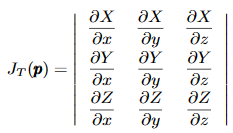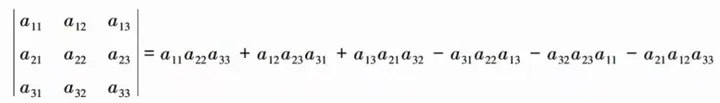

function [detXYZ] = XYZ_jacobi3_det(XYZ)
[dXx,dXy,dXz] = imgradientxyz(XYZ(:,:,:,1));
[dYx,dYy,dYz] = imgradientxyz(XYZ(:,:,:,2));
[dZx,dZy,dZz] = imgradientxyz(XYZ(:,:,:,3));

detXYZ = dXx.*dYy.*dZz + dXy.*dYz.*dZx + dXz.*dYx.*dZy - dXz.*dYy.*dZx - dXx.*dYz.*dZy - dXy.*dYx.*dZz;
detXYZ = detXYZ/85184;
end

function [output] = XYZ_jacobi3_mat(XYZ)
[dXx,dXy,dXz] = imgradientxyz(XYZ(:,:,:,1));
[dYx,dYy,dYz] = imgradientxyz(XYZ(:,:,:,2));
[dZx,dZy,dZz] = imgradientxyz(XYZ(:,:,:,3));

mask = any(XYZ,4);
mask = imgaussfilt3(single(mask),0.5)>0.999;

A = [dXx(:),dXy(:),dXz(:), dYx(:),dYy(:),dYz(:), dZx(:),dZy(:),dZz(:)];
A = A';
A = reshape(A,3,3,[]);
Ams = A(:,:,mask(:));
E = zeros(size(A,3),3);
E(mask(:),:) = mat_svd3(Ams);
% [Lambda1,Lambda2,Lambda3]=eig3volume(Dxx,Dxy,Dxz,Dyy,Dyz,Dzz);
E1 = reshape(E(:,1),size(dXx));
E2 = reshape(E(:,2),size(dXx));
E3 = reshape(E(:,3),size(dXx));

output = {E1,E2,E3};
end

function output = XYZ_fit_affine(sXYZ,varargin)
XYZ = sXYZ.data;
[ny,nx,nz,nc] = size(XYZ);
[X,Y,Z] = meshgrid(1:nx,1:ny,1:nz);
mask = mean(XYZ,4)>0; % 部分变形场别mask掉
T_affine.data = 0*XYZ;

regress_B = zeros(4); regress_B(end) = 1;
for i = 1:3
    mri_val = XYZ(:,:,:,i);
    regress_val = [X(mask),Y(mask),Z(mask),0*X(mask)+1];
    regress_b = regress(mri_val(mask),regress_val);
    regress_B(i,:) = regress_b;
    T_affine.data(:,:,:,i) = regress_b(1)*X+regress_b(2)*Y+regress_b(3)*Z+regress_b(4);
end
T_fuse = T_affine;
T_fuse.data = T_affine.data.*(1-mask)+XYZ.*mask;

output = {T_affine,T_fuse,regress_B};
end

位移场（相对值，可负）==> 坐标场（绝对值，正定）

function sXYZ = XYZ_mov2abs(sXYZ)
temp = XYZ_field_linear(sXYZ);
sXYZ.data = sXYZ.data + temp.data;
end

function sXYZ = XYZ_field_linear(sXYZ)
sz = size(sXYZ.data);
[X,Y,Z] = meshgrid(1:sz(2),1:sz(1),1:sz(3));
sXYZ.data = cat(4,X,Y,Z);
end

function sXYZ = XYZ_resize(sXYZ,new_sz)
sz = size(sXYZ.data,1:3);
sXYZ = MRI_func_ROI(sXYZ,'imresize3',new_sz);

temp = size(sXYZ.data,1:3)./sz;
temp = temp([2,1,3]);
for i = 1:3
    sXYZ.data(:,:,:,i) = sXYZ.data(:,:,:,i)*temp(i);
end
end


smooth field

function T_in = XYZ_smooth(T_in,varargin)
options_default = struct('smoothness',[],'smooth_mask',[]);
[options, eval_str] = resolve_input(options_default,varargin);
eval(eval_str);

if smoothness == 0
    smoothness = [];
end

% smooth_func = @(x,sm) smooth3(x,'gaussian',3*sm,sm);
smooth_func = @(x,sm) imgaussfilt3(x,sm);

if ~isempty(smoothness)
    if length(smoothness)>1
        smooth_num = smoothness(2);
    else
        smooth_num = 1;
    end
    smoothness = smoothness(1);
    if ~isempty(smooth_mask)
        if ndims(smooth_mask) < 3
            smooth_mask = T_in.data>0;
        end
        smooth_mask = double(smooth_mask);
        for i_dim = 1:3
            smooth_mask(:,:,:,i_dim) = smooth_func(smooth_mask(:,:,:,i_dim),smoothness);
        end
    else
        smooth_mask = 1;
    end
    for i = 1:smooth_num
        for i_dim = 1:3
            T_in.data(:,:,:,i_dim) = smooth_func(T_in.data(:,:,:,i_dim),smoothness);
        end
        if mod(i,2) == 1
            T_in.data = T_in.data./(1e-6+smooth_mask);
        end
    end
end
end

保持变形场的对称性，例如对于X轴对称的图谱配准

function sXYZ = XYZ_sym_dim(sXYZ,dim,cen)
if nargin<3
    cen = sXYZ;
end
if isstruct(cen)
    cen = cen.data;
end
if ndims(cen)>=3
    shape = size(cen,[2,1,3]);
    cen = shape(dim)/2;
end

temp = sXYZ.data(:,:,:,dim);
if dim==1
    sXYZ.data(:,:,:,dim) = (temp + (2*cen-fliplr(temp)))/2;
else
    sXYZ.data(:,:,:,dim) = (temp + fliplr(temp))/2;
end
end

利用镜像配准使图像对称

function sXYZ = XYZ_sym_field(sXYZ)
sz = sXYZ.size;
[X,Y,Z] = meshgrid(1:sz(2),1:sz(1),1:sz(3));
sXYZ.data = (sXYZ.data + cat(4,X,Y,Z))/2;
end

合并多次变形场（串联）

function output = XYZ_combine(Tcell,inv_dir,varargin)
if nargin<2
    inv_dir = 1;
end

if inv_dir
    Tcell = Tcell(end:-1:1); % 多个变形场串联，需要反向变形顺序
end

T = Tcell{1};
for i = 2:length(Tcell)
    T = MRI_warp(T,Tcell{i});
end

output = {T};
end